# JW ARX Plot Livescript

% Run after DSPSA_JW_Cycles or load saved data
% Run each section separately (third section still has issues if ran from saved data)
load 230-4inp-240623-Gatt-iter20.mat
[evset finalavgs]

ans =     1.0000    1.0000         0         0         0   91.8148   48.8092   54.2829   50.9987
    1.0000         0    1.0000         0         0   89.2523   79.5852   80.7010   80.0315
    1.0000         0         0    1.0000         0   66.8572   64.7364   56.9067   61.6045
    1.0000         0         0         0    1.0000   88.5950   80.6715   81.0830   80.8361
         0    1.0000    1.0000         0         0   84.6400   53.7261   54.2391   53.9313
         0    1.0000         0    1.0000         0   92.3464   79.5313   78.8462   79.2572
         0    1.0000         0         0    1.0000   87.1343   83.1133   81.8893   82.6237
         0         0    1.0000    1.0000         0   86.8568   82.7880   81.5546   82.2946
         0         0    1.0000         0    1.0000   53.6583   65.7824   57.8219   62.5982
         0         0         0    1.0000    1.0000   86.3996   84.0589   82.2623   83.3402


finalcycles

finalcycles =     1.0000    1.0000         0         0         0   92.5071   91.1225   73.3358   40.5041   32.5879
    1.0000         0    1.0000         0         0   90.7932   77.4990   87.7115   82.2374   79.0193
    1.0000         0         0    1.0000         0   84.6007   88.2716   69.0744   49.1137   36.8633
    1.0000         0         0         0    1.0000   89.5171   83.5347   72.5357   85.9442   87.6728
         0    1.0000    1.0000         0         0   85.8837   86.6613   82.6187   39.4192   35.8754
         0    1.0000         0    1.0000         0   85.5005   92.2572   72.7772   92.4357   80.3161
         0    1.0000         0         0    1.0000   87.8246   89.3361   75.4388   86.0764   84.9324
         0         0    1.0000    1.0000         0   89.9505   78.5600   85.9107   87.8030   79.8534
         0         0    1.0000         0    1.0000   79.1641   66.7733   60.7977   51.4097   46.5189
         0         0         0    1.0000    1.0000   89.2765   87.7816   75.1


for q = 1:1:20
    [mfit(q,:) msetit(q,:)] = max(setdata(q).fititer); % Gets max iteration from each SPSA run per set
    mfeatures(q,:) = round(setdata(q).w(msetit(q),:));
end
[msetfit mset] = max(mfit) % Best set of est/val cycles based on SPSA objective function

msetfit = 84.1568

mset = 11

mfeatures % Features used in the best spsa iteration for each est/val cycle

mfeatures =      1     0     1     0     0     1     1     1
     1     1     1     0     1     0     0     0
     1     0     0     0     0     0     0     1
     1     1     1     0     1     0     0     0
     1     0     1     1     1     1     1     0
     1     1     1     1     0     0     0     1
     1     1     1     0     0     1     0     0
     1     1     1     0     0     0     0     0
     1     0     1     0     0     0     1     0
     1     1     1     0     0     0     0     0


%mfit % Objective function value of best spsa iteration for each est/val cycle



q = mset; % Choose which set of est/val cycles to plot ('mset' gives the best est/val set based on the SPSA objective function)

maxit = msetit(q) % Best SPSA iteration (k) for set q

maxit = 16


k = length(setdata(q).fititer);

% Get names of inputs from final solution after BSPSA
ww = setdata(q).w; % Extract w values for all iterations for set q
wwfinal = round(ww(maxit,:));
inputspace = find(wwfinal ==1); %find which inputs are being used
    dspsainputs = overall.InputName(inputspace) %prints names of the inputs used (including interaction terms)

dspsainputs = 4×1 cell array
    {'Goals'          }
    {'Expected Points'}
    {'Granted Points' }
    {'Temperature'    }



 arxmodelw = setarx(q).arxmodel

arxmodelw =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 0.04219 z^-1 - 0.01538 z^-2           
                                                   
  B1(z) = -1.001 + 1.085 z^-1                      
                                                   
  B2(z) = -41.24 z^-1                              
                                                   
  B3(z) = 40.95                                    
                                                   
  B4(z) = 44 - 49.35 z^-1 + 10.03 z^-2             
                                                   
Sample time: 1 days
  
Parameterization:
   Polynomial orders:   na=2   nb=[2 1 1 3]   nk=[0 1 0 0]
   Number of free coefficients: 9
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                        
Estimated using ARX on time domain data "iodataw".             
Fit to estimation data: [79.46 89.92 82.68]% (prediction focus)
FPE: 3.937

 iodata = getexp(overall,find(evset(q,:)==1));

 iodata_allw = [overall2.y overall2.u(:,inputspace)];

ny = 1; % Only 1 output

st = 1;
it1=1

it1 = 1


[arxove_results percentovefit] = compare(overall2(:,outputchannels,inputchannels(inputspace)), arxmodelw);
percentovefit = (1-(norm(iodata_allw(:,it1)-arxove_results.y(:,it1)))/(norm(iodata_allw(:,it1) - mean(iodata_allw(:,it1)) )))*100

percentovefit = 81.7148

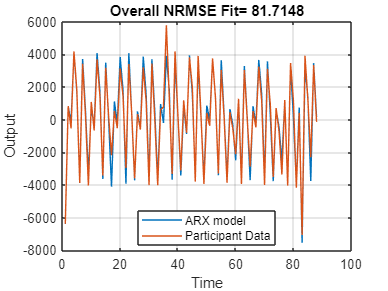


% figure;
% plot(1:length(arxove_results.y),arxove_results.y,1:length(arxove_results.y),overall2.y)
%         legend('ARX model','Participant Data','location','best')
%         xlabel('Time')
%         ylabel('Output')
%         title(['Overall NRMSE Fit= ' num2str(percentovefit)])  

figure;
    plot(1:length(arxove_results.y),arxove_results.y);hold on;
    plot(1:length(arxove_results.y),overall2.y)
    legend('ARX model','Participant Data','location','best')
    xlabel('Time')
    ylabel('Output')
    title(['Overall NRMSE Fit= ' num2str(percentovefit)])  
    grid;

% Plot per cycle
     iodata1 = getexp(overall,1); 
     iodata2 = getexp(overall,2);
     iodata3 = getexp(overall,3);
     iodata4 = getexp(overall,4);
     iodata5 = getexp(overall,5);

     iodata1q = [iodata1.y iodata1.u(:,inputspace)];
     [arx_result_1 percent_arx_1]=compare(iodata1q,arxmodelw);

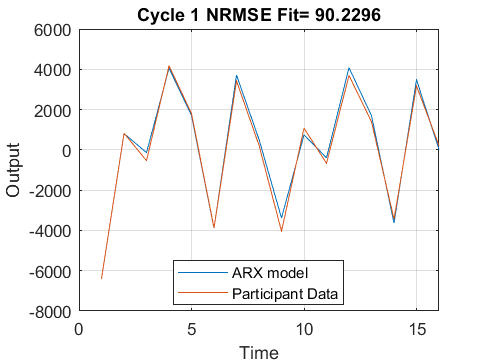


figure;     
% plot(1:length(arx_result_1),arx_result_1,1:length(arx_result_1),iodata1.y)
plot(1:length(arx_result_1),arx_result_1);hold on;
plot(1:length(arx_result_1),iodata1.y)

legend('ARX model','Participant Data','location','best')
xlabel('Time')
ylabel('Output')
title(['Cycle 1 NRMSE Fit= ' num2str(percent_arx_1)])  
grid

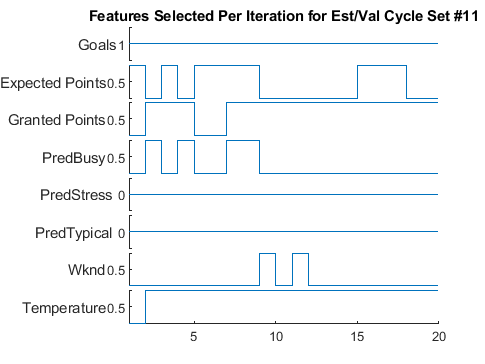

       
 % Feature Selection       
allw = setdata(q).w;
binput = round(allw);
[birow, bicol] = size(binput);
 figure
 featureplot = stackedplot(binput,'Title',['Features Selected Per Iteration for Est/Val Cycle Set #' num2str(q)],'DisplayLabels',overall.InputName(indx_inp));   
   for i = 1:bicol
        featureplot.LineProperties(i).PlotType = 'stairs';
   end

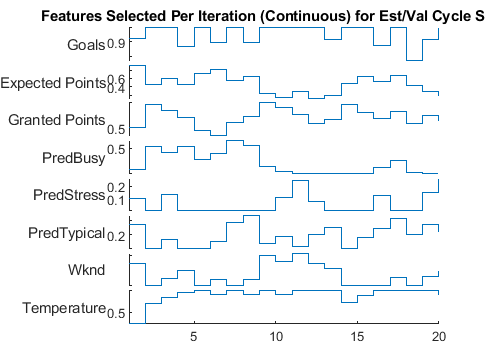


 figure
 featureplotc = stackedplot(allw,'Title',['Features Selected Per Iteration (Continuous) for Est/Val Cycle Set #' num2str(q)],'DisplayLabels',overall.InputName(indx_inp));   
   for i = 1:bicol
        featureplotc.LineProperties(i).PlotType = 'stairs';
   end

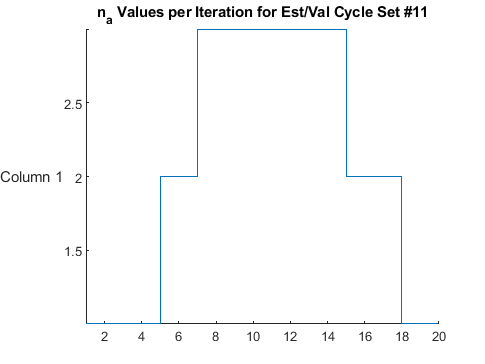


% Plot ARX Orders   
allna = setdata(q).na;
figure
    naplot = stackedplot(round(allna),'Title',['n_a Values per Iteration for Est/Val Cycle Set #' num2str(q)]);
        naplot.LineProperties.PlotType = 'stairs';

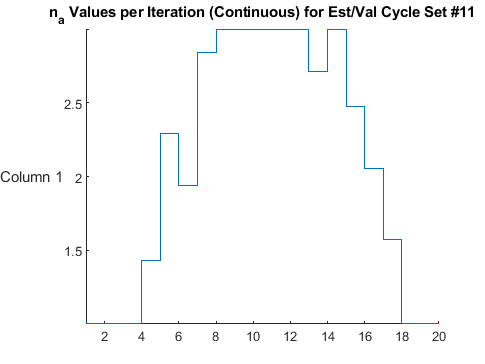

figure
    naplotc = stackedplot(allna,'Title',['n_a Values per Iteration (Continuous) for Est/Val Cycle Set #' num2str(q)]);
        naplotc.LineProperties.PlotType = 'stairs';

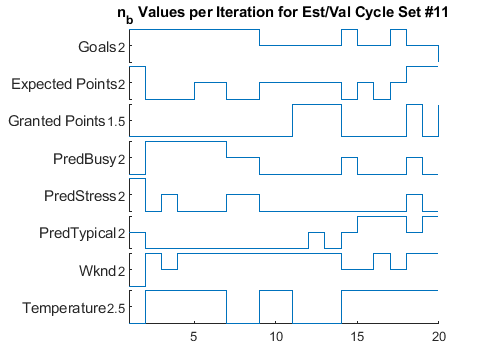


allnb = setdata(q).nb;
figure
    nbplot = stackedplot(round(allnb),'Title',['n_b Values per Iteration for Est/Val Cycle Set #' num2str(q)],'DisplayLabels',overall.InputName(indx_inp));
        for i = 1:1:bicol
            nbplot.LineProperties(i).PlotType = 'stairs';
        end

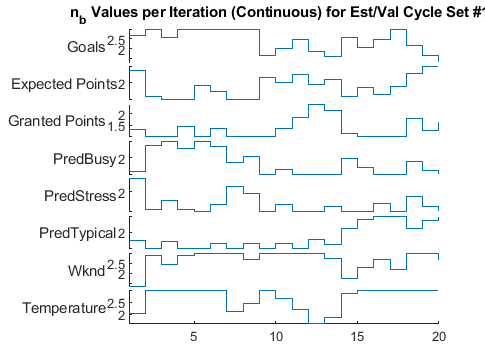

figure
    nbplotc = stackedplot(allnb,'Title',['n_b Values per Iteration (Continuous) for Est/Val Cycle Set #' num2str(q)],'DisplayLabels',overall.InputName(indx_inp));
        for i = 1:1:bicol
            nbplotc.LineProperties(i).PlotType = 'stairs';
        end

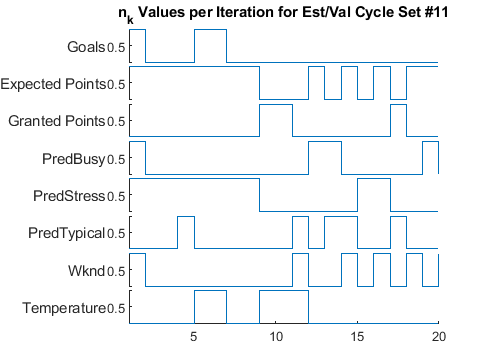


allnk = setdata(q).nk;        
figure
    nkplot = stackedplot(round(allnk),'Title',['n_k Values per Iteration for Est/Val Cycle Set #' num2str(q)],'DisplayLabels',overall.InputName(indx_inp));
        for i = 1:1:bicol
            nkplot.LineProperties(i).PlotType = 'stairs';
        end

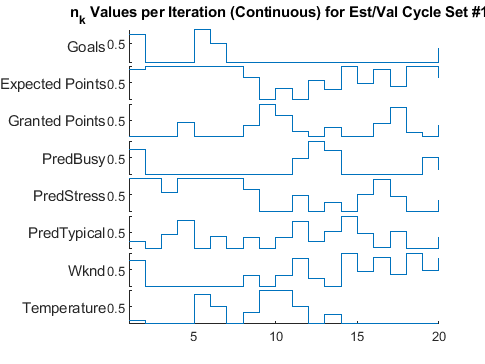


figure
    nkplotc = stackedplot(allnk,'Title',['n_k Values per Iteration (Continuous) for Est/Val Cycle Set #' num2str(q)],'DisplayLabels',overall.InputName(indx_inp));
        for i = 1:1:bicol
            nkplotc.LineProperties(i).PlotType = 'stairs';
        end

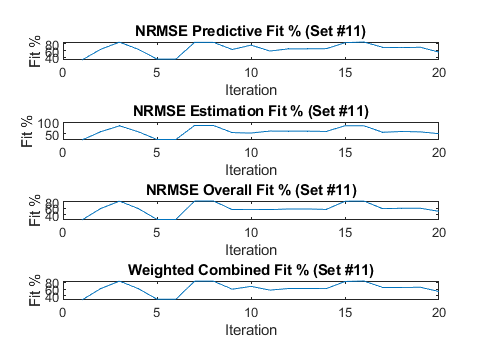

 
figure %Plot iterations for the set of est/val data
    subplot(4,1,1)
        plot(1:k,setdata(q).valfit)
        title(['NRMSE Predictive Fit % (Set #' num2str(q),')']);
        xlabel('Iteration');
        ylabel('Fit %')
    subplot(4,1,2)
        plot(1:k,setdata(q).estfit)
        title(['NRMSE Estimation Fit % (Set #' num2str(q),')']);
        xlabel('Iteration');
        ylabel('Fit %')
    subplot(4,1,3)
        plot(1:k,setdata(q).ovefit)
        title(['NRMSE Overall Fit % (Set #' num2str(q),')']);
        xlabel('Iteration');
        ylabel('Fit %')
    subplot(4,1,4)
        plot(1:k,setdata(q).fititer)
        title(['Weighted Combined Fit % (Set #' num2str(q),')']);
        xlabel('Iteration');
        ylabel('Fit %');   

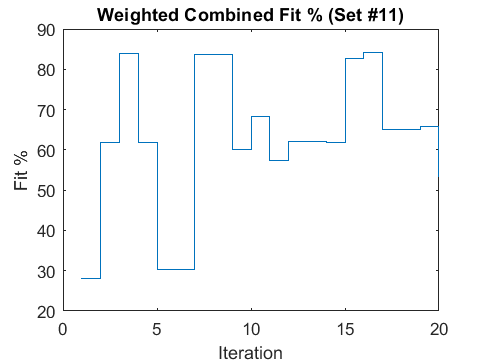


 figure;
        stairs(1:k,setdata(q).fititer)
        title(['Weighted Combined Fit % (Set #' num2str(q),')']);
        xlabel('Iteration');
        ylabel('Fit %');   

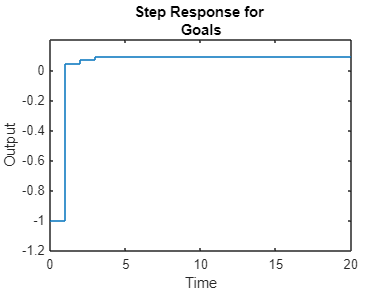

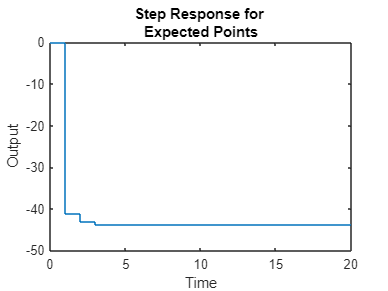

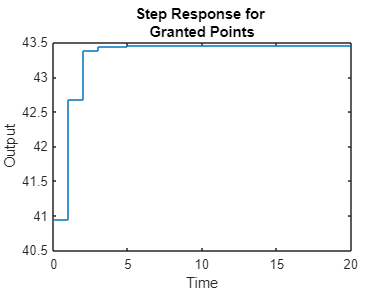

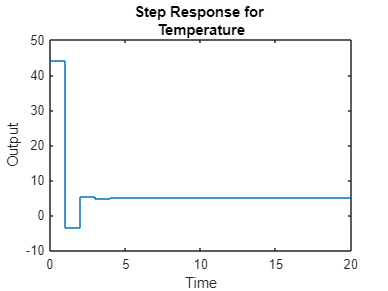

%  figure; % Step Response from Best Model -- Revise to look better
 [stepy stept] = step(arxmodelw); 
 [as bs cs] = size(stepy);
 stepinp = find(round(allw(maxit,:)) == 1); % To number inputs in case of feature selection
 
 for stepi = 1:1:cs
     figure;
     stairs(stept,stepy(:,:,stepi))
     title(['Step Response for ' overall.Inputname(stepinp(stepi))])
     xlabel('Time')
     ylabel('Output')
 end

fitper = 81.7148

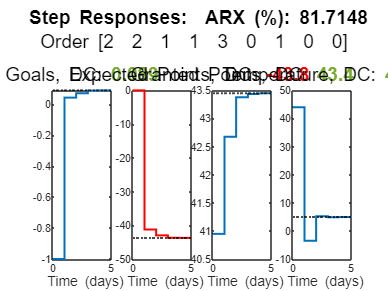


 CustomStep(arxmodelw,[arxmodelw.na arxmodelw.nb arxmodelw.nk], overall2(:,outputchannels,inputchannels(inputspace)),[0:5],"Step_Goal_Att")

%  mod_val=16
%  arxmodel2=setarx(mod_val).arxmodel
%  CustomStep2(arxmodel2,[arxmodel2.na arxmodel2.nb arxmodel2.nk],[0:20],"Step_Goal_Att_model_3")


% figure;
% subplot(2,2,1);stackedplot(featureplot.XData,featureplot.YData)
% subplot(2,2,2);stackedplot(naplot.XData,naplot.YData)
% subplot(2,2,3);stackedplot(nbplot.XData,nbplot.YData)
% subplot(2,2,4);stackedplot(nkplot.XData,nkplot.YData)


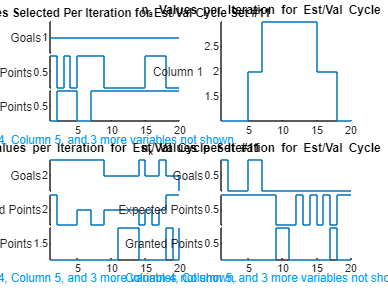

allna = setdata(q).na;
figure;

subplot(2,2,1);

featureplot = stackedplot(binput,'Title',['Features Selected Per Iteration for Est/Val Cycle Set #' num2str(q)],'DisplayLabels',overall.InputName(indx_inp));   
   for i = 1:bicol
        featureplot.LineProperties(i).PlotType = 'stairs';
   end

subplot(2,2,2);
    naplot = stackedplot(round(allna),'Title',['n_a Values per Iteration for Est/Val Cycle Set #' num2str(q)]);
        naplot.LineProperties.PlotType = 'stairs';
allnb = setdata(q).nb;
subplot(2,2,3);
    nbplot = stackedplot(round(allnb),'Title',['n_b Values per Iteration for Est/Val Cycle Set #' num2str(q)],'DisplayLabels',overall.InputName(indx_inp));
        for i = 1:1:bicol
            nbplot.LineProperties(i).PlotType = 'stairs';
        end

        subplot(2,2,4);
allnk = setdata(q).nk;        
    nkplot = stackedplot(round(allnk),'Title',['n_k Values per Iteration for Est/Val Cycle Set #' num2str(q)],'DisplayLabels',overall.InputName(indx_inp));
        for i = 1:1:bicol
            nkplot.LineProperties(i).PlotType = 'stairs';
        end

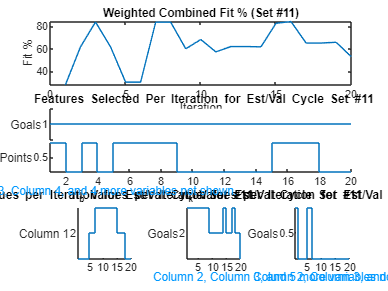

allna = setdata(q).na;
figure;

subplot(3,3,1:3);
plot(1:k,setdata(q).fititer)
title(['Weighted Combined Fit % (Set #' num2str(q),')']);
xlabel('Iteration');
ylabel('Fit %');   


subplot(3,3,4:6);
featureplot = stackedplot(binput,'Title',['\bf Features Selected Per Iteration for Est/Val Cycle Set #' num2str(q)],'DisplayLabels',overall.InputName(indx_inp));   
   for i = 1:bicol
        featureplot.LineProperties(i).PlotType = 'stairs';
   end

subplot(3,3,7);
    naplot = stackedplot(round(allna),'Title',['\bf n_a Values per Iteration for Est/Val Cycle Set #' num2str(q)]);
        naplot.LineProperties.PlotType = 'stairs';
allnb = setdata(q).nb;

subplot(3,3,8);
    nbplot = stackedplot(round(allnb),'Title',['\bf n_b Values per Iteration for Est/Val Cycle Set #' num2str(q)],'DisplayLabels',overall.InputName(indx_inp));
        for i = 1:1:bicol
            nbplot.LineProperties(i).PlotType = 'stairs';
        end

subplot(3,3,9);
allnk = setdata(q).nk;        
    nkplot = stackedplot(round(allnk),'Title',['\bf n_k Values per Iteration for Est/Val Cycle Set #' num2str(q)],'DisplayLabels',overall.InputName(indx_inp));
        for i = 1:1:bicol
            nkplot.LineProperties(i).PlotType = 'stairs';
        end

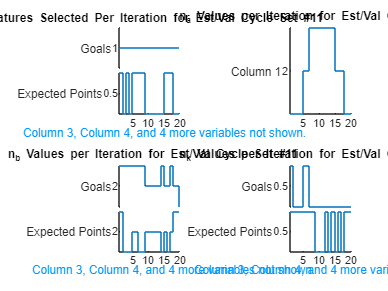

allna = setdata(q).na;
figure;

subplot(2,2,1)
featureplot = stackedplot(binput,'Title',['\bf Features Selected Per Iteration for Est/Val Cycle Set #' num2str(q)],'DisplayLabels',overall.InputName(indx_inp));   
   for i = 1:bicol
        featureplot.LineProperties(i).PlotType = 'stairs';
   end

subplot(2,2,2);
    naplot = stackedplot(round(allna),'Title',['\bf n_a Values per Iteration for Est/Val Cycle Set #' num2str(q)]);
        naplot.LineProperties.PlotType = 'stairs';
allnb = setdata(q).nb;

subplot(2,2,3);
    nbplot = stackedplot(round(allnb),'Title',['\bf n_b Values per Iteration for Est/Val Cycle Set #' num2str(q)],'DisplayLabels',overall.InputName(indx_inp));
        for i = 1:1:bicol
            nbplot.LineProperties(i).PlotType = 'stairs';
        end

subplot(2,2,4);
allnk = setdata(q).nk;        
    nkplot = stackedplot(round(allnk),'Title',['\bf n_k Values per Iteration for Est/Val Cycle Set #' num2str(q)],'DisplayLabels',overall.InputName(indx_inp));
        for i = 1:1:bicol
            nkplot.LineProperties(i).PlotType = 'stairs';
        end


%   savedata = 1; % Works, but does not save everything you need quite yet.
% 
%   filename = '230-4inp-240623-GAtt';
%   if exist([filename, '.mat'],'file') == 2
%        error('File name already exists -- rename file')
%   else
%      if savedata == 1
%         save(filename,'setdata','estvaldata','setarx','finalavgs','finalcycles','overall','overall2','evset','setcyc1','setcyc2','setcyc3','setcyc4','setcyc5','indx_inp','time','weights', 'gainfs','gainarx','outputchannels','inputchannels');
%      end
%   
%   end

  